# Euler Method Code:

clc
clear all

## Interval

a = 0; % start
b = 5; % end

n = 10; % number of iterations
h = (b - a) / n; % step size

## Discretization

x = a:h:b;
y = zeros (size(x));

## Initial Condition

y(1) = 1;

## **Differential ** Equation y' = 2x + y

for i = 1: n - 1 % loop
    f = 2*x(i) + y(i); % f(x_n, y_n)
    y(i+1) = y(i) + h*f; % y_(n+1) = y_n + hf(x_n, y_n)
end

## Plot

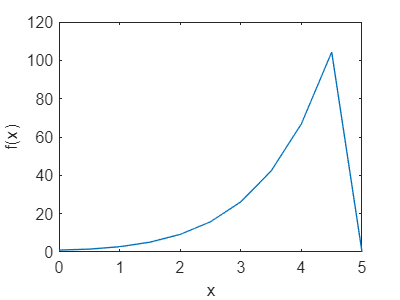

figure (1)
plot(x, y)
xlabel ('x')
ylabel('f(x)')